% AAE 364L Lab5 MATLAB Code
% TOMOKI KOIKE  
clear all; close all; clc;
set(groot, 'defaulttextinterpreter','latex');
set(groot, 'defaultAxesTickLabelInterpreter','latex');
set(groot, 'defaultLegendInterpreter','latex');

lqr_xc_data = load("koike_lab5_lqr_xc.mat");
lqr_ang_data = load("koike_lab5_lqr_ang.mat");
pp_xc_data = load("koike_lab5_pp_xc.mat");
pp_ang_data = load("koike_lab5_pp_ang.mat");

% LQR
t = lqr_xc_data.x_and_command_part3.time;
xc = lqr_xc_data.x_and_command_part3.signals.values(:,1);
command = lqr_xc_data.x_and_command_part3.signals.values(:,2);
theta = lqr_ang_data.theta_part3.signals.values;

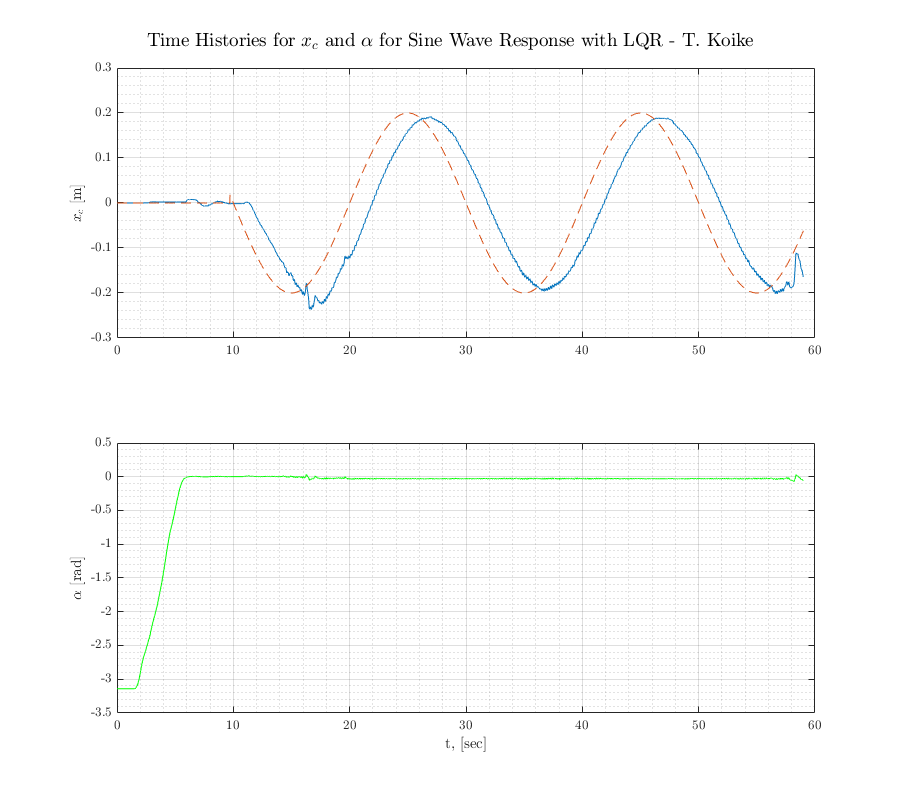

% Plotting 
fig = figure('Renderer',"painters", 'Position', [10 10 900 800]);
subplot(2,1,1)
plot(t,xc)
grid on; grid minor; box on; hold on;
plot(t, command, '--')
hold off
ylabel('$x_c$ [m]')
subplot(2,1,2)
plot(t,theta, '-g')
grid on; grid minor; box on;
ylabel('$\alpha$ [rad]')
xlabel('t, [sec]')
sgtitle('Time Histories for $x_c$ and $\alpha$ for Sine Wave Response with LQR - T. Koike')
saveas(fig, 'response_lqr.png')

% PP
t = pp_xc_data.x_and_command_part3.time;
xc = pp_xc_data.x_and_command_part3.signals.values(:,1);
command = pp_xc_data.x_and_command_part3.signals.values(:,2);
theta = pp_ang_data.theta_part3.signals.values;

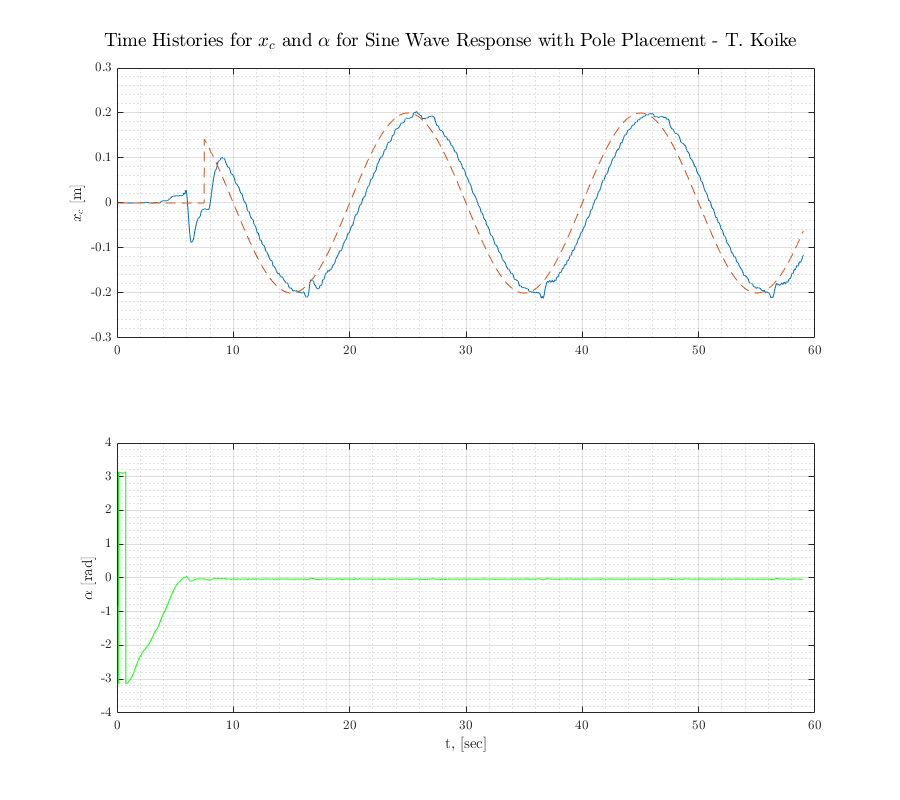

% Plotting 
fig = figure('Renderer',"painters", 'Position', [10 10 900 800]);
subplot(2,1,1)
plot(t,xc)
grid on; grid minor; box on; hold on;
plot(t, command, '--')
hold off
ylabel('$x_c$ [m]')
subplot(2,1,2)
plot(t,theta, '-g')
grid on; grid minor; box on;
ylabel('$\alpha$ [rad]')
xlabel('t, [sec]')
sgtitle('Time Histories for $x_c$ and $\alpha$ for Sine Wave Response with Pole Placement - T. Koike')
saveas(fig, 'response_pp.png')